x_train = [1 ,2 , 4 ,6 ,7 ,9 , 10 , 12 , 14, 15 , 17 ,18, 20 ,21,22,24,25,26 ]

x_train =      1     2     4     6     7     9    10    12    14    15    17    18    20    21    22    24    25    26


y_train = [99.6 ,99.33 , 98.4 , 97.6 , 97.31 , 96.76 , 96.4 , 95.2 , 94.71 , 93.92 , 93.18 , 93 , 92.64 , 91.62 ,  91.49 , 90.84 , 90.6 , 90.4]

y_train =    99.6000   99.3300   98.4000   97.6000   97.3100   96.7600   96.4000   95.2000   94.7100   93.9200   93.1800   93.0000   92.6400   91.6200   91.4900   90.8400   90.6000   90.4000


plot(x_train,y_train)
hold on
x_test = [3 , 5 , 8 , 11 , 13 , 16 , 19 , 23]

x_test =      3     5     8    11    13    16    19    23


y_test = [103.25 , 100.61 , 97.49 , 98.4 , 100 , 101.5 , 103 , 106.1]

y_test =   103.2500  100.6100   97.4900   98.4000  100.0000  101.5000  103.0000  106.1000


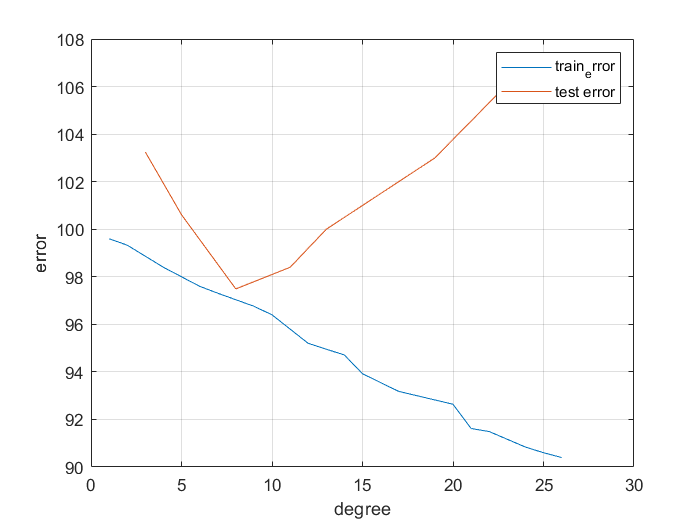

plot(x_test,y_test)
legend('train_error',"test error")

grid on
xlabel('degree')
ylabel('error')



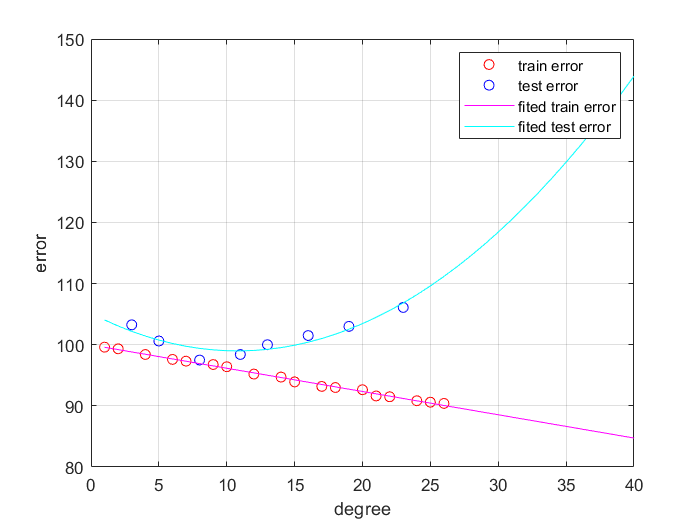

x =1:40;
poly_train = polyfit(x_train,y_train,1);
poly_test = polyfit(x_test,y_test,2);
train_prid = polyval(poly_train , x);
test_prid  = polyval(poly_test , x);
figure
plot(x_train,y_train , 'or')
hold on
plot(x_test,y_test , 'ob')
hold on
plot(x,train_prid,"m")
hold on
plot(x,test_prid,"c")
hold on
legend('train error',"test error",'fited train error','fited test error')
grid on
xlabel('degree')
ylabel('error')